# Generate a List of Tables in a Report

Create a list of tables as an `mlreportgen.dom.LOT` object. To include tables in the list:

- Create titles for the tables as `mlreportgen.dom.Paragraph` objects.

- Associate the `Paragraph` objects with a numbering stream that has the name `table`.

Import the DOM package so that you do not have to use long, fully qualified class names.

import mlreportgen.dom.*

Create a report.

d = Document("DOM Report with List of Tables","docx");

Create a list of tables container and append it to the report.

lotObj = LOT();
append(d,lotObj);
append(d,PageBreak);

Create a table.

t1 = Table(magic(2));

Create a paragraph for the table title. 

p1 = Paragraph("Table ");

Create an automatic numbering stream with the name `table` and associate it with the paragraph. 

append(p1,AutoNumber("table"));

Increment the counter for the numbering stream.

p1.Style = {CounterInc("table"),WhiteSpace("preserve")};

Append the rest of the title text to the paragraph and append the paragraph to the report.

append(p1,".");
append(p1," Order 2 Magic Square");
append(d,p1);

Append the table to the report after the table title.

append(d,t1);

Create another table and a title for the table. Associate the `table` numbering stream with the table title and increment the numbering counter. 

t2 = Table(magic(3));
p2 = Paragraph("Table ");
append(p2,AutoNumber("table"));
p2.Style = {CounterInc("table"),WhiteSpace("preserve")};

Append the rest of the title text to the paragraph and append the paragraph to the report.

append(p2,".");
append(p2, " Order 3 Magic Square");
append(d,p2);

Append the table to the report after the table title.

append(d,t2);

Close and view the report.

close(d);
rptview(d);

Here is the list of tables in the generated report:

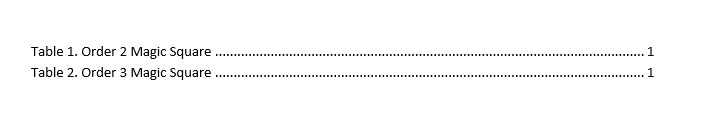

*Copyright 2020 The MathWorks, Inc.*